Total Number of training data points (segments): 7020


     rec_rest       3159 
     rest_rest      3159 


     rec_rest       351 
     rest_rest      351 


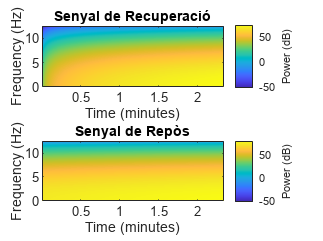

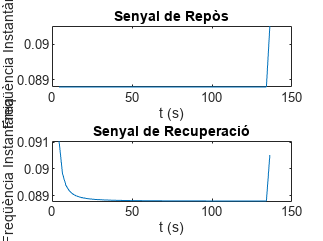

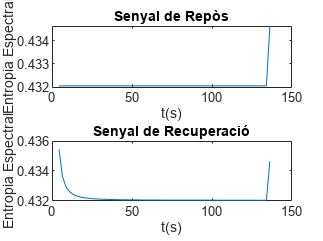

ans = 57×1 cell array
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}
    {2×30 double}


ans = 0.0888

ans = 0.4321

ans = -0.5296

ans = -0.5743

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

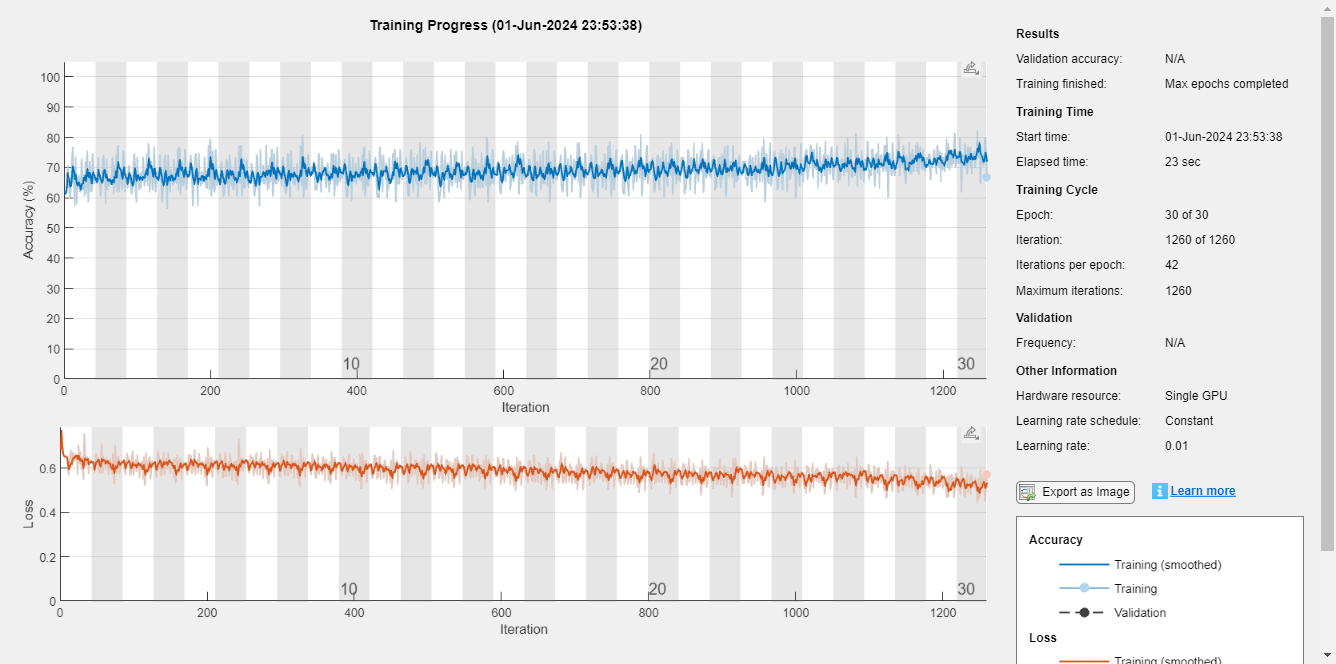

LSTMAccuracy = 74.0266

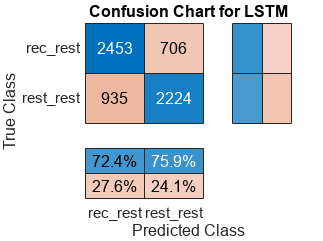

LSTMAccuracy = 72.5071

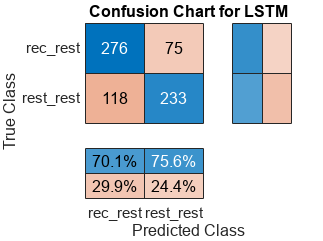

% Load the data
load('VORTAL_rec_data 1.mat'); 

dataRec = data;

load('VORTAL_rest_data.mat'); 
dataRest = data;

nsub = 39; % Number of subjects
fs = 25; % Sampling frequency
segmentLength = 30 * fs; % Segment length
Signals = {}; % Initialize cell array to store signals
Labels = {}; % Initialize cell array to store labels
matIndex = 1; % Index for the cell arrays

numSignalsRecovery = 90; % Number of recovery signals to extract per subject
numSignalsRest = 90; % Number of rest signals to extract per subject

% Process the recovery data
for n = 1:nsub
    signal = dataRec(n).ref.resp_sig.paw.v; % Extract the signal
    signalLength = length(signal);
    restStart = 6501;
    restEnd = signalLength - 40 * fs;

    for s = 1:numSignalsRecovery
        if restEnd >= restStart + segmentLength - 1
            ini = randi([restStart, restEnd - segmentLength + 1], 1, 1);
            endIdx = ini + segmentLength - 1;
            Signals{matIndex} = signal(ini:endIdx);
            Labels{matIndex} = 'rec_rest';
            matIndex = matIndex + 1;
        end
    end
end

% Process the rest data
for n = 1:nsub
    signal = dataRest(n).ref.resp_sig.paw.v; % Extract the signal
    signalLength = length(signal);
    restStart = 1 + 30 * fs;
    restEnd = signalLength - 40 * fs;

    for s = 1:numSignalsRest
        if restEnd >= restStart + segmentLength - 1
            ini = randi([restStart, restEnd - segmentLength + 1], 1, 1);
            endIdx = ini + segmentLength - 1;
            Signals{matIndex} = signal(ini:endIdx);
            Labels{matIndex} = 'rest_rest';
            matIndex = matIndex + 1;
        end
    end
end

Signals = Signals(1:matIndex-1); % Remove any extra preallocated space
Labels = categorical(Labels(1:matIndex-1)); % Convert labels to categorical

Signals = Signals';
Labels = Labels';

fprintf('Total Number of training data points (segments): %d\n', matIndex-1);

% Identify indices for recovery and rest labels
idxRecovery = find(Labels == 'rec_rest');
idxRest = find(Labels == 'rest_rest');

% Randomly divide signals into training and testing sets
[trainIndRecovery, ~, testIndRecovery] = dividerand(length(idxRecovery), 0.9, 0.0, 0.1);
[trainIndRest, ~, testIndRest] = dividerand(length(idxRest), 0.9, 0.0, 0.1);

% Extracting training and testing datasets using logical indexing
XTrain = [Signals(idxRecovery(trainIndRecovery)); Signals(idxRest(trainIndRest))];
YTrain = [Labels(idxRecovery(trainIndRecovery)); Labels(idxRest(trainIndRest))];

XTest = [Signals(idxRecovery(testIndRecovery)); Signals(idxRest(testIndRest))];
YTest = [Labels(idxRecovery(testIndRecovery)); Labels(idxRest(testIndRest))];

% Summary for verification
summary(YTrain); 
summary(YTest);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ORIGINAL DATA LSTM TRAINING (COMMENTED OUT)
% Define LSTM network architecture
% layers = [ ...
%     sequenceInputLayer(1)
%     bilstmLayer(100, 'OutputMode', 'last')
%     fullyConnectedLayer(2)
%     softmaxLayer
%     classificationLayer
% ];
% 
% options = trainingOptions('adam', ...
%     'MaxEpochs', 10, ...
%     'MiniBatchSize', 150, ...
%     'InitialLearnRate', 0.01, ... 
%     'GradientThreshold', 2, ... 
%     'GradientThresholdMethod', 'l2norm', ... 
%     'SequenceLength', 1000, ...
%     'ExecutionEnvironment', "auto", ...
%     'Plots', 'training-progress', ...
%     'Verbose', false);
% 
% net = trainNetwork(XTrain, YTrain, layers, options);
%  
% % Classify testing data
% trainPred = classify(net, XTrain, 'SequenceLength', 1000);
% 
% % Training accuracy
% LSTMAccuracy = sum(trainPred == YTrain) / numel(YTrain) * 100
% figure
% confusionchart(YTrain, trainPred, 'ColumnSummary', 'column-normalized', ...
%               'RowSummary', 'row-normalized', 'Title', 'Confusion Chart for LSTM');
% 
% % Classify testing data
% testPred = classify(net, XTest, 'SequenceLength', 1000);
% 
% % Testing accuracy
% LSTMAccuracy = sum(testPred == YTest) / numel(YTest) * 100
% figure
% confusionchart(YTest, testPred, 'ColumnSummary', 'column-normalized', ...
%               'RowSummary', 'row-normalized', 'Title', 'Confusion Chart for LSTM');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% IMPROVE PERFORMANCE USING SPECTRAL FEATURES

% Spectrogram
figure
subplot(2,1,1);
pspectrum(idxRecovery, fs, 'spectrogram', 'TimeResolution', 0.5)
title('Senyal de Recuperació')

subplot(2,1,2);
pspectrum(idxRest, fs, 'spectrogram', 'TimeResolution', 0.5)
title('Senyal de Repòs')

% Instantaneous frequency
[instFreqRecovery, tRecovery] = instfreq(idxRecovery, fs);
[instFreqRest, tRest] = instfreq(idxRest, fs);

figure
subplot(2,1,1);
plot(tRest, instFreqRest)
title('Senyal de Repòs')
xlabel('t (s)')
ylabel('Freqüència Instantània')

subplot(2,1,2);
plot(tRecovery, instFreqRecovery)
title('Senyal de Recuperació')
xlabel('t (s)')
ylabel('Freqüència Instantània')

% Apply instfreq to each cell in training and testing data
instfreqTrain = cellfun(@(x) instfreq(x, fs)', XTrain, 'UniformOutput', false);
instfreqTest = cellfun(@(x) instfreq(x, fs)', XTest, 'UniformOutput', false);

% Spectral entropy
[pentropyRecovery, tRecovery2] = pentropy(idxRecovery, fs);
[pentropyRest, tRest2] = pentropy(idxRest, fs);

figure
subplot(2,1,1)
plot(tRest2, pentropyRest)
title('Senyal de Repòs')
xlabel('t(s)')
ylabel('Entropia Espectral')

subplot(2,1,2)
plot(tRecovery2, pentropyRecovery)
title('Senyal de Recuperació')
xlabel('t(s)')
ylabel('Entropia Espectral')

% Apply pentropy to each cell in training and testing data
pentropyTrain = cellfun(@(x) pentropy(x, fs)', XTrain, 'UniformOutput', false);
pentropyTest = cellfun(@(x) pentropy(x, fs)', XTest, 'UniformOutput', false);

% Concatenate the features to create 2D input
XTrain2 = cellfun(@(x,y) [x; y], instfreqTrain, pentropyTrain, 'UniformOutput', false);
XTest2 = cellfun(@(x,y) [x; y], instfreqTest, pentropyTest, 'UniformOutput', false);

% Standardize data
mean(instFreqRest);
mean(pentropyRest);

XV = [XTrain2{:}];
mu = mean(XV, 2);
sg = std(XV, [], 2);

XTrainSD = XTrain2;
XTrainSD = cellfun(@(x) (x - mu) ./ sg, XTrainSD, 'UniformOutput', false);

XTestSD = XTest2;
XTestSD = cellfun(@(x) (x - mu) ./ sg, XTestSD, 'UniformOutput', false);

instFreqNSD = XTrainSD{1}(1, :);
pentropyNSD = XTrainSD{1}(2, :);

mean(instFreqNSD);
mean(pentropyNSD);

% Modify network architecture for 2D input
layers = [ ...
    sequenceInputLayer(2)
    bilstmLayer(100, 'OutputMode', 'last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ];

options = trainingOptions('adam', ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment', "auto", ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train LSTM network with time-frequency features
net2 = trainNetwork(XTrainSD, YTrain, layers, options);

% Predict on training data
trainPred2 = classify(net2, XTrainSD);
LSTMAccuracy = sum(trainPred2 == YTrain) / numel(YTrain) * 100
figure
confusionchart(YTrain, trainPred2, 'ColumnSummary', 'column-normalized', ...
              'RowSummary', 'row-normalized', 'Title', 'Confusion Chart for LSTM');

% Predict on testing data
testPred2 = classify(net2, XTestSD);

% Calculate and display testing accuracy
LSTMAccuracy = sum(testPred2 == YTest) / numel(YTest) * 100
figure
confusionchart(YTest, testPred2, 'ColumnSummary', 'column-normalized', ...
              'RowSummary', 'row-normalized', 'Title', 'Confusion Chart for LSTM');
